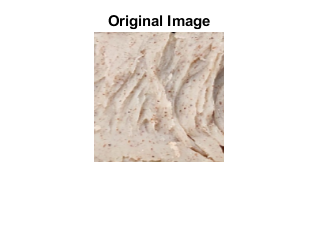

clear;
% Read the image
img = imread('4.png');

% Display the original image
figure;
imshow(img);
title('Original Image');

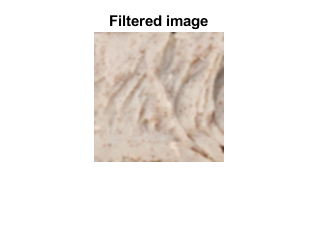


% Apply Gaussian filtering for noise reduction
img_filtered = imgaussfilt(img, 1); % Adjust the standard deviation (sigma) as needed

% Show filtered image
figure;
imshow(img_filtered);
title('Filtered image');

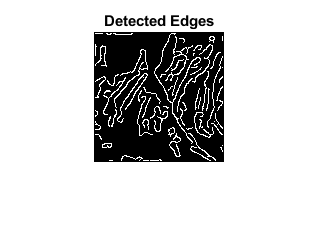


% Convert to grayscale
img_gray = rgb2gray(img_filtered);

% Edge detection using Canny method (you can experiment with other methods)
edges = edge(img_gray, 'Canny');

% Display the edges
figure;
imshow(edges);
title('Detected Edges');


% Extract edges properties
edges_props = regionprops(edges, 'PixelList');

% Calculate image dimensions in mm
image_width_mm = 20; % Width of the object in mm
image_height_mm = 20; % Height of the object in mm

% Pixel-to-mm conversion ratio
pixel_to_mm_ratio_width = size(img, 2) / image_width_mm;
pixel_to_mm_ratio_height = size(img, 1) / image_height_mm;

% Initialize arrays to store edge parameters
num_edges = numel(edges_props);
edge_angles = zeros(1, num_edges);
edge_distances = zeros(1, num_edges);
edge_lengths = zeros(1, num_edges);

% Calculate parameters for each edge
for i = 1:num_edges
    pixel_list = edges_props(i).PixelList;
    
    % Ensure at least 2 points to compute the path length
    if size(pixel_list, 1) < 2
        continue;
    end
    
    try
        % Compute edge direction using the slope of the line
        direction_vector = pixel_list(end, :) - pixel_list(1, :);
        edge_angles(i) = atan2d(direction_vector(2), direction_vector(1)); % Angle in degrees
        
        % Calculate distance between edges (horizontal center-to-center)
        center_x = size(img, 2) / 2; % Horizontal center of the image
        distances = abs(pixel_list(:, 1) - center_x);
        edge_distances(i) = mean(distances) / pixel_to_mm_ratio_width; % Mean distance in mm
        
        % Calculate maximum path length of each edge in mm
        edge_lengths(i) = max(pdist(pixel_list)) / sqrt(pixel_to_mm_ratio_width^2 + pixel_to_mm_ratio_height^2); % Maximum path length in mm
    catch
        continue;
    end
end

% Display the extracted parameters
disp(['Number of Edges: ', num2str(num_edges)]);

Number of Edges: 69


disp(['Edge Angles (degrees): ', num2str(edge_angles)]);

Edge Angles (degrees): 0      63.4349      10.3048     -11.3099      63.4349      54.4623      39.8056      12.5288     -37.6942     -9.46232            0     -28.6105          -45            0      -65.556            0     -41.3086     -55.0975            0           45     -53.1301     -66.0375      49.3987      39.4725            0     -21.8014            0     -13.4486     -17.1027     -21.8014      11.3099     -42.7974     -36.8699      26.5651           45     -36.8699     -68.9625     -66.8014     -61.8214      30.9638      76.7595      60.2551     -9.46232           45     -32.4712      30.9638     -9.46232     -57.1715      -20.556            0      41.8202     -71.5651     -68.1986       69.444     -78.6901     -81.0274     -76.8094      21.8014     -57.9946           45            0      64.9831     -65.2249     -54.4623     -33.6901      63.4349           90            0            0


disp(['Distances between Edges (mm): ', num2str(edge_distances)]);

Distances between Edges (mm): 9.1538      9.6805       8.618      8.9504      9.5214      9.3303      9.1189      7.9066      7.0179      7.8817      7.6154      7.0059      7.5692      7.3077         6.8      5.4545      3.8689      4.0608      4.1106      2.5385      2.9135      1.8639      1.9145     0.98143      1.9231     0.51459     0.52071      2.7202     0.62051     0.59829      1.1923      3.0413      1.8022      1.9822      2.6667      2.8185      2.4923      2.5552      3.8592      3.7385      3.6218      4.0549        4.75      6.7473      5.8022       6.188      5.5769      7.1501      6.0891      5.4231      6.7713      5.9077      6.3077      6.4977      7.2025      7.6308       8.594      8.2344      8.7115      9.0615           0      9.1903      9.3603      9.5096      9.5692      9.7179      9.8462           0           0


disp(['Maximum Path Lengths of Edges (mm): ', num2str(edge_lengths)]);

Maximum Path Lengths of Edges (mm): 0.7615      1.19664      2.33573      2.48546     0.652714     0.973009     0.849643      1.07141      4.62819     0.688021     0.543928      1.46356      1.09328     0.326357      1.89986      2.06693      6.95973      6.04519      2.29484      4.29256      1.21626      2.34331      1.17166      2.46154     0.543928      1.56893      1.19664      12.1626      2.48308     0.634324       0.5547      4.80877     0.615385      1.03203      2.52326       1.7709      2.03228      1.96116      3.94339     0.634324      1.89986     0.929465     0.661717      4.15385      1.41839      2.56743     0.661717      4.48535      1.02628     0.243252      3.06536      2.32557      1.21626     0.985096      4.29256      2.40315       7.8725     0.729756      2.05256      1.69231            0      1.80072      1.65697      1.13576     0.729756     0.486504     0.435143            0            0
